% Create Maze
n = 10;
maze = [1 1 1 1 -50 1 -50 1 1 1; -50 -50 -50 1 -50 1 1 1 -50 1; 1 1 1 1 -50 -50 1 -50 -50 -50; ...
    -50 1 -50 -50 -50 1 1 1 1 1; -50 1 1 -50 1 1 -50 1 -50 1; ...
    -50 -50 1 -50 -50 -50 -50 1 -50 1; 1 1 1 1 1 1 1 1 -50 1; ...
    1 -50 1 -50 1 1 -50 1 -50 1; 1 -50 -50 1 -50 1 -50 1 -50 -50; ...
    1 1 1 1 1 1 -50 1 1 10];
maze(1,1) = 1; % Start
maze(n,n) = 10; % Goal
disp(maze)

     1     1     1     1   -50     1   -50     1     1     1
   -50   -50   -50     1   -50     1     1     1   -50     1
     1     1     1     1   -50   -50     1   -50   -50   -50
   -50     1   -50   -50   -50     1     1     1     1     1
   -50     1     1   -50     1     1   -50     1   -50     1
   -50   -50     1   -50   -50   -50   -50     1   -50     1
     1     1     1     1     1     1     1     1   -50     1
     1   -50     1   -50     1     1   -50     1   -50     1
     1   -50   -50     1   -50     1   -50     1   -50   -50
     1     1     1     1     1     1   -50     1     1    10



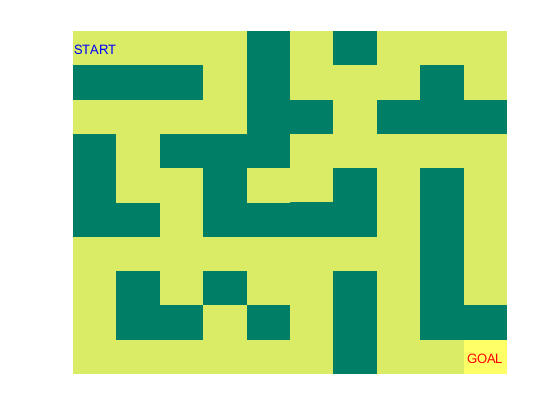


% Visualize Maze
n = length(maze);
figure
imagesc(maze)
colormap(summer)
text(1,1,'START','HorizontalAlignment','center', 'Color', 'blue')
text(n,n,'GOAL','HorizontalAlignment','center', 'Color', 'red')
axis off

Goal = n*n;
fprintf('Goal is at: %d', Goal)

Goal is at: 100


% Reward System
% Up = (i-n);            % Possible Directions to take
% Down = (i+n);
% Left = (i-1);
% Right = (i+1);

reward=zeros(n*n);
for i=1:Goal
    reward(i,:)=reshape(maze',1,Goal);
end
for i=1:Goal
    for j=1:Goal
        if j~=i-n  && j~=i+n  && j~=i-1 && j~=i+1
            reward(i,j)=-Inf;
        end    
    end
end

% Q-Learning Algorithm
q = randn(size(reward));        % Initialize Q-Maxtix set goal state
gamma = 0.9;                    % Discount Factor - determines the importance of future rewards
                                % 0 = short-sighted 1 = long-term high reward.
alpha = 0.2;                    % Explore vs exploit (Learning Rate) - Step size determines to what extent newly acquired information overrides old information 
                                % 0 = learn nothing, 1 = consider only the most recent information, ignore prior knowledge to explore possibilites 
maxItr = 50;                    % Max iteration - Number of attempts till it quits

for i=1:maxItr                  % Starting position
    currentState = 1;           % Repeat till Goal is reached
    while(1)                    % Possible actions for chosen state
    n_actions = find(reward(currentState,:)>0);                % Choose next action at random and set it as the nextState
    nextState = n_actions(randi([1 length(n_actions)],1,1));     % Find all the possible actions for the selected state
        n_actions=find(reward(nextState,:)>=0);                  % Find the max q-value i.e. nextState with best action
        max_q = 0;
        for j=1:length(n_actions)
            max_q = max(max_q,q(nextState,n_actions(j)));
        end
        q(currentState,nextState)=reward(currentState,nextState)+gamma*max_q;    % Updates the q-value (Bellman's Equation)
        if (currentState == Goal)                                                       % Check whether the goal has been reached
            break;
        end
        currentState=nextState;        % Update currentState
    end
end

% Solving the Maze
start = 1;
move = 0;
path = start;

while(move~=Goal)
    [~,move]=max(q(start,:));
    if ismember(move,path)                        % Deleting chances of getting stuck in small loops  (upto order of 4)
        [~,x]=sort(q(start,:),'descend');
        move=x(2);
        if ismember(move,path)
            [~,x]=sort(q(start,:),'descend');
            move=x(3);
            if ismember(move,path)
                [~,x]=sort(q(start,:),'descend');
                move=x(4);
                if ismember(move,path)
                    [~,x]=sort(q(start,:),'descend');
                    move=x(5);
                end
            end
        end
    end
    path=[path,move];                             % Appending next action/move to the path
    start=move;
end

% Solution of Maze
fprintf('Final Path: %s', num2str(path))

Final Path: 1    2    3    4   14   24   23   22   32   42   43   53   63   64   65   66   67   68   78   88   98   99  100

fprintf('Total number of steps taken: %d', length(path))

Total number of steps taken: 23

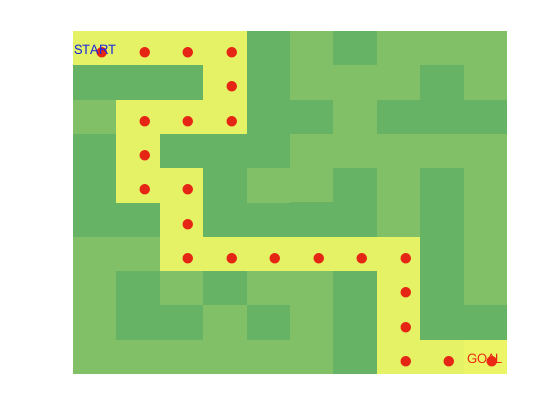


pmat=zeros(n,n);                                  % reproducing path to matrix path
[q, r]=quorem(sym(path),sym(n));
q=double(q);r=double(r);
q(r~=0)=q(r~=0)+1;r(r==0)=n;
for i=1:length(q)
    pmat(q(i),r(i))=50;
end
figure                                            % Final Plot of the maze
imagesc(pmat)
colormap(white)
for i=1:n
    for j=1:n
        if pmat(i,j)==50
            text(j,i,'\bullet','Color','red','FontSize',20)
        end
    end
end
text(1,1,'START','HorizontalAlignment','center', 'Color', 'blue')
text(n,n,'GOAL','HorizontalAlignment','center', 'Color', 'red')
hold on
imagesc(maze,'AlphaData',0.2)
colormap(summer)
hold off
axis off